Modelo del robot usando RST

L0=6.15*0.1;  
L1=1.00*0.1;
L2=8.40*0.1;
L3=1.35*0.1;
L4=7.55*0.1;
L5=0.85*0.1;
L4_1=sqrt(L4^2+L3^2);

robotabb_rst=rigidBodyTree;

dhparams=[  0   0       L0    0 ;
           L1   pi/2    0     pi/2 ;
           L2   pi/2    0     pi ;
           L3   pi/2    0     pi/2+atan(135/755) ;
           L4_1 0       0     atan(755/135) ;
            0   pi/2    L5    0];

link1=rigidBody('link1');
link1.Joint=rigidBodyJoint('art1','revolute');
link2=rigidBody('link2');
link2.Joint=rigidBodyJoint('art2','revolute');
link3=rigidBody('link3');
link3.Joint=rigidBodyJoint('art3','revolute');
link4=rigidBody('link4');
link4.Joint=rigidBodyJoint('art4','revolute');
link5=rigidBody('link5');
link5.Joint=rigidBodyJoint('art5','revolute');
link6=rigidBody('link6');
link6.Joint=rigidBodyJoint('art6','revolute');

setFixedTransform(link1.Joint,dhparams(1,:),'mdh');
setFixedTransform(link2.Joint,dhparams(2,:),'mdh');
setFixedTransform(link3.Joint,dhparams(3,:),'mdh');
setFixedTransform(link4.Joint,dhparams(4,:),'mdh');
setFixedTransform(link5.Joint,dhparams(5,:),'mdh');
setFixedTransform(link6.Joint,dhparams(6,:),'mdh');

addBody(robotabb_rst,link1,'base')
addBody(robotabb_rst,link2,'link1')
addBody(robotabb_rst,link3,'link2')
addBody(robotabb_rst,link4,'link3')
addBody(robotabb_rst,link5,'link4')
addBody(robotabb_rst,link6,'link5')

showdetails(robotabb_rst)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        link1         art1     revolute             base(0)   link2(2)  
   2        link2         art2     revolute            link1(1)   link3(3)  
   3        link3         art3     revolute            link2(2)   link4(4)  
   4        link4         art4     revolute            link3(3)   link5(5)  
   5        link5         art5     revolute            link4(4)   link6(6)  
   6        link6         art6     revolute            link5(5)   
--------------------


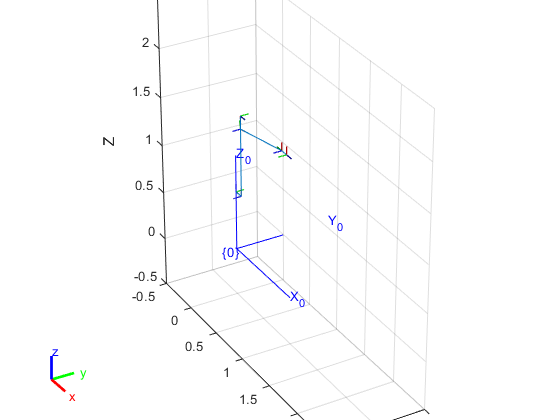


config = homeConfiguration(robotabb_rst);
config(1).JointPosition = 0;
config(2).JointPosition = pi/2;
config(3).JointPosition = pi;
config(4).JointPosition = pi/2+atan(135/755);
config(5).JointPosition = atan(755/135);
config(6).JointPosition = 0;

show(robotabb_rst,config);
hold on
trplot(eye(4),'frame','{0}')
xlim([-0.5 2.5])
ylim([-0.5 0.5])
zlim([-0.5 2.5])
view([60 30])
hold off

Modelo geométrico directo

MTH_01=trotx(dhparams(1,2))*transl(dhparams(1,1),0,0)*trotz(dhparams(1,4))*transl(0,0,dhparams(1,3));
MTH_12=trotx(dhparams(2,2))*transl(dhparams(2,1),0,0)*trotz(dhparams(2,4))*transl(0,0,dhparams(2,3));
MTH_23=trotx(dhparams(3,2))*transl(dhparams(3,1),0,0)*trotz(dhparams(3,4))*transl(0,0,dhparams(3,3));
MTH_34=trotx(dhparams(4,2))*transl(dhparams(4,1),0,0)*trotz(dhparams(4,4))*transl(0,0,dhparams(4,3));
MTH_45=trotx(dhparams(5,2))*transl(dhparams(5,1),0,0)*trotz(dhparams(5,4))*transl(0,0,dhparams(5,3));
MTH_56=trotx(dhparams(6,2))*transl(dhparams(6,1),0,0)*trotz(dhparams(6,4))*transl(0,0,dhparams(6,3));
MTH_06=MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*eye(4);

Verificación de los puntos de calibración usando cinemática directa:

format shortG
q=[0,0;0,60;0,-65;-110,60;-110,-18.3;100,60;100,-65];
Puntos=zeros(6,2);
EfectorFinal=zeros(4,4,7);
for i=1:7
    MTH_01=trotx(dhparams(1,2))*transl(dhparams(1,1),0,0)*trotz(dhparams(1,4))*transl(0,0,dhparams(1,3));
    MTH_12=trotx(dhparams(2,2))*transl(dhparams(2,1),0,0)*trotz(dhparams(2,4)+deg2rad(q(i,1)))*transl(0,0,dhparams(2,3));
    MTH_23=trotx(dhparams(3,2))*transl(dhparams(3,1),0,0)*trotz(dhparams(3,4))*transl(0,0,dhparams(3,3));
    MTH_34=trotx(dhparams(4,2))*transl(dhparams(4,1),0,0)*trotz(dhparams(4,4)+deg2rad(q(i,2)))*transl(0,0,dhparams(4,3));
    MTH_45=trotx(dhparams(5,2))*transl(dhparams(5,1),0,0)*trotz(dhparams(5,4))*transl(0,0,dhparams(5,3));
    MTH_56=trotx(dhparams(6,2))*transl(dhparams(6,1),0,0)*trotz(dhparams(6,4))*transl(0,0,dhparams(6,3));
    MTH_06=MTH_01*MTH_12*MTH_23*MTH_34*MTH_45;
    EfectorFinal(:,:,i)=MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*eye(4);
    Puntos(i,1)=MTH_06(1,4)*1000;
    Puntos(i,2)=MTH_06(3,4)*1000;
    disp("Posición en x: "+Puntos(i,1)+", posición en z: "+Puntos(i,2))
end

Posición en x: 855, posición en z: 1455
Posición en x: 360.5866, posición en z: 2041.3492
Posición en x: 541.4283, posición en z: 692.7911
Posición en x: 1351.2039, posición en z: -117.7114
Posición en x: 400.4949, posición en z: -302.3005
Posición en x: -1349.9301, posición en z: 623.9447
Posición en x: -53.2625, posición en z: 1036.2138


Las matriz de cosenos directores del efector final en cada punto de calibración es

format short
for i=1:7
    disp("Punto de calibración "+(i-1))
    disp(EfectorFinal(1:3,1:3,i))
end

Punto de calibración 0


    0.0000   -0.0000    1.0000
    0.0000   -1.0000   -0.0000
    1.0000    0.0000   -0.0000



Punto de calibración 1


   -0.8660   -0.0000    0.5000
    0.0000   -1.0000    0.0000
    0.5000    0.0000    0.8660



Punto de calibración 2


    0.9063   -0.0000    0.4226
    0.0000   -1.0000   -0.0000
    0.4226    0.0000   -0.9063



Punto de calibración 3


    0.7660    0.0000    0.6428
    0.0000   -1.0000   -0.0000
    0.6428    0.0000   -0.7660



Punto de calibración 4


    0.7848    0.0000   -0.6198
    0.0000   -1.0000   -0.0000
   -0.6198    0.0000   -0.7848



Punto de calibración 5


   -0.3420   -0.0000   -0.9397
    0.0000   -1.0000    0.0000
   -0.9397    0.0000    0.3420



Punto de calibración 6


   -0.5736   -0.0000    0.8192
    0.0000   -1.0000   -0.0000
    0.8192    0.0000    0.5736



La pose del efector final en cada punto de calibración usando coordenadas generalizadas es

for i=1:7
    disp("Pose del efector en el punto de calibración "+(i-1))
    posicion=EfectorFinal(1:3,4,i);
    orientacion=tr2rpy(EfectorFinal(:,:,i),'deg');
    disp([posicion;orientacion'])
end

Pose del efector en el punto de calibración 0


    0.9400
    0.0000
    1.4550
         0
   90.0000
  180.0000



Pose del efector en el punto de calibración 1


    0.4031
    0.0000
    2.1150
   -0.0000
   30.0000
  180.0000



Pose del efector en el punto de calibración 2


    0.5774
   -0.0000
    0.6158
  180.0000
   25.0000
    0.0000



Pose del efector en el punto de calibración 3


    1.4058
    0.0000
   -0.1828
  180.0000
   40.0000
   -0.0000



Pose del efector en el punto de calibración 4


    0.3478
   -0.0000
   -0.3690
  180.0000
  -38.3000
   -0.0000



Pose del efector en el punto de calibración 5


   -1.4298
    0.0000
    0.6530
   -0.0000
  -70.0000
  180.0000



Pose del efector en el punto de calibración 6


    0.0164
   -0.0000
    1.0850
    0.0000
   55.0000
  180.0000



Espacio de trabajo:

Límites de movimiento de las articulaciones son entre

1: +180 y -180.

2: +110 y -100.

3: +65 y -60.

4: +200 y -200.

5: +120 y -120.

6. +400 y -400.

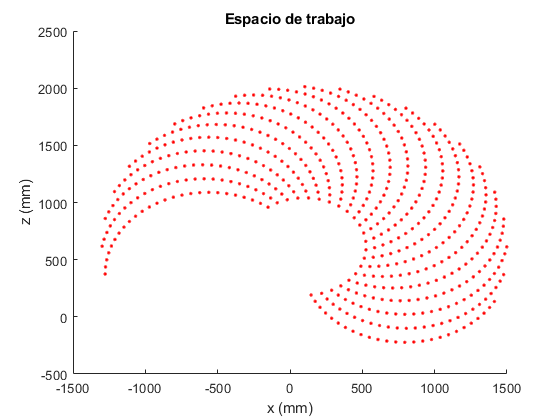

figure()
MTH_01=trotx(dhparams(1,2))*transl(dhparams(1,1),0,0)*trotz(dhparams(1,4))*transl(0,0,dhparams(1,3));
MTH_23=trotx(dhparams(3,2))*transl(dhparams(3,1),0,0)*trotz(dhparams(3,4))*transl(0,0,dhparams(3,3));
MTH_56=trotx(dhparams(6,2))*transl(dhparams(6,1),0,0)*trotz(dhparams(6,4))*transl(0,0,dhparams(6,3));
m=0;
ValorMax1=zeros(13,1);
ValorMax2=zeros(26,3);
Puntos_x=zeros(13,1);
Puntos_y=zeros(13,1);
cont=0; cont2=0;
for i=-100:10:110
    for j=-60:5:65
        for k=-120:120:120
            cont=cont+1;
            MTH_12=trotx(dhparams(2,2))*transl(dhparams(2,1),0,0)*trotz(dhparams(2,4)+deg2rad(i))*transl(0,0,dhparams(2,3));
            MTH_34=trotx(dhparams(4,2))*transl(dhparams(4,1),0,0)*trotz(dhparams(4,4)+deg2rad(j))*transl(0,0,dhparams(4,3));
            MTH_45=trotx(dhparams(5,2))*transl(dhparams(5,1),0,0)*trotz(dhparams(5,4)+deg2rad(k))*transl(0,0,dhparams(5,3));
            EfectorFinal_matriz=MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*eye(4);
            Puntos_x(cont,1)=EfectorFinal_matriz(1,4)*1000;
            Puntos_y(cont,1)=EfectorFinal_matriz(3,4)*1000;
            ValorMax1(cont,1)=sqrt((100-Puntos_x(cont,1))^2+(615-Puntos_y(cont,1))^2);
        end
        indice=find(max(ValorMax1));
        cont=0;
        cont2=cont2+1;
        ValorMax2(cont2,1:3)=[Puntos_x(indice,1),Puntos_y(indice,1),max(ValorMax)];
        scatter(Puntos_x(indice,1),Puntos_y(indice,1),'r.')
        hold on
    end
    indice=find(max(ValorMax2(:,3)));
    scatter(ValorMax2(indice,1),ValorMax2(indice,2),'r.')
    hold on
    cont2=0;
end
title("Espacio de trabajo")
xlabel('x (mm)')
ylabel('z (mm)')
hold off